**Setup**

clc;
clear;
tic
po = [0 0 0]; % point of our plane, here simply the origin
no = [0 1 0]; % normal vector of the plane i.e. pointing along the y-axis
num = 10000;
trials = 1;
areas = zeros(num,1,'double');
results = zeros(trials,2,'double');
g = [0 0 0];
beta = 0;

**Create the shape**

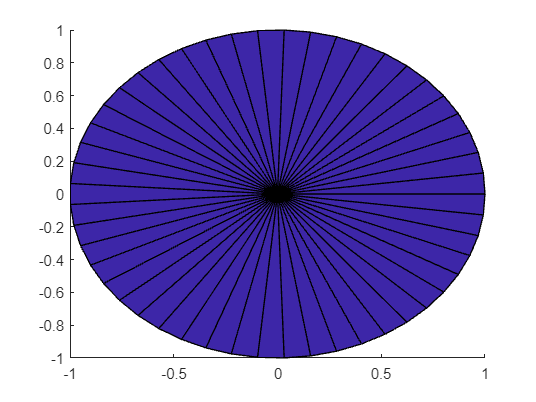

% [x,y] = pol2cart(deg2rad(0:120:360),1); %to create a pyramid
% x1 = [x*0; x; x*0];
% y1 = [y*0; y; y*0];
% z1 = [x*0+sqrt(2); x*0; x*0];
% s = surface(x1, y1, z1);

% coord = [...          %to create a cube
%     0    0    0;
%     0.5  0    0;
%     0.5  0.5  0;
%     0    0.5  0;
%     0    0    0.5;
%     0.5  0    0.5;
%     0.5  0.5  0.5;
%     0    0.5  0.5;];
% idx = [4 8 5 1 4; 1 5 6 2 1; 2 6 7 3 2; 3 7 8 4 3; 5 8 7 6 5; 1 4 3 2 1]';
% x1 = coord(:,1)*2;
% y1 = coord(:,2)*2;
% z1 = coord(:,3)*2;
% s = surface(x1(idx), y1(idx), z1(idx));

R=1; r=1; H=2; nCS=2; nNodes=50; %to create a cone/cylinder
z=linspace(-H/2,H/2,nCS);
m=-(R-r)/H;
b=0.5*(R+r);
r_local=m*z+b;
th=linspace(0,2*pi,nNodes);
[th,r_local]=meshgrid(th,r_local);
[x1,y1]=pol2cart(th,r_local);
z1=repmat(z',1,nNodes);
x1 = [zeros(1, nNodes); x1];
y1 = [zeros(1, nNodes); y1];
z1 = [-H/2*ones(1,nNodes); z1];
s = surface(x1, y1, z1);

**Get a random uniform sample of *****num***** points on a sphere. **(https://uk.mathworks.com/matlabcentral/fileexchange/37004-suite-of-functions-to-perform-uniform-sampling-of-a-sphere)

for j=1:1:trials
    V=RandSampleSphere(num,'uniform');

**Run the pyramid rotation using the previously acquired points on a sphere.**

    for k = 1:length(V)

**Get x-z projection of the shape**

        %get data as a result of rotation
        XX = get(s,'xdata');
        YY = get(s,'ydata');
        ZZ = get(s,'zdata');
        % concat the pyramid grid
        gr = [XX(:) YY(:) ZZ(:)];
        v = gr - repmat(po,numel(XX(:)),1);
        % dot vector with the normal vector of the plane of intrest
        % this represents the distance from the grid points to our plane along the normal
        d = v(:,1)*no(1) + v(:,2)*no(2) + v(:,3)*no(3); 
        % get the projected points
        projected_grid = gr - d .* repmat(no,numel(XX(:)),1);
        projected_grid = unique(projected_grid,'rows','stable');
        %we need the outer points of the region, acquire this and the area of
        %the region with convex hull.
        [shadow,area] = convhull(projected_grid(:,1),projected_grid(:,3));
        areas(k) = area;
        %plot(projected_grid(shadow,1),projected_grid(shadow,3))

**Rotate the shape**

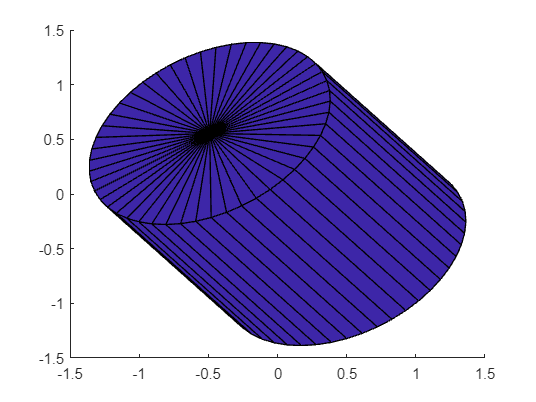

        a = [V(k,1), V(k,2), 0];
        b = [0 0 2];
        if norm(g)==0; g = cross(a,b); continue; end %if the magnitude of the cross product is zero, then continue to the next iteration
        rotate(s,g,rad2deg(beta), [0 0 0]);
        g = cross(a,b); %find the cross product between a and b
        beta = acos(V(k,3));        
        rotate(s,g,-rad2deg(beta), [0 0 0]);
%         drawnow
    end
    results(j,1) = mean(areas);
    results(j,2) = toc;
end

results

results =     4.7094   11.6899
